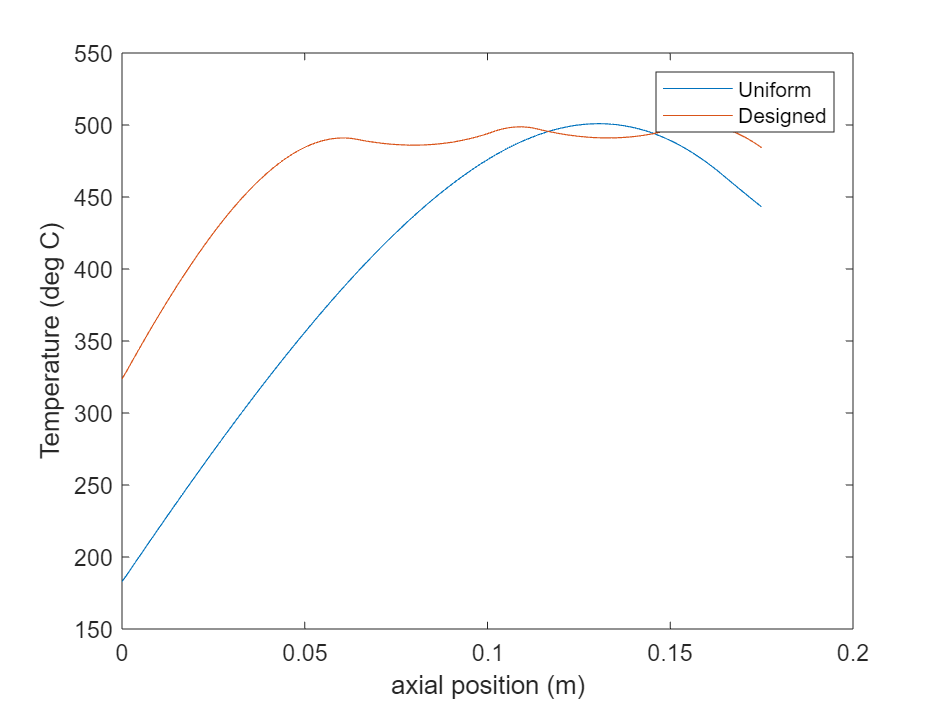

clear all 

%{
    This program is used to compile and then rank the predicted temperature
    profiles of the 2^14 different reactor configurations for an infinite
    AC resistance ratio accounting for non-negligile radial temperature
    gradients. 
    The data sorted here was created using sweep1.mat calling
    Temp_Crinf_wRadial.mat function. 
%}

load("Crinfty_wRadial_10_12246.mat"); %from structure number 10 to 12256 

ind=1; 


for n=10:12255

number=dec2bin(n); %binary number representing reactor configuration
structure=[]; %array of 1's and 0's representing high conductivity (1) and low conductivity (0) sections

for i=1:length(number)
    structure(i)=str2num(number(i)); %convert binary string entries to numbers
end

if length(number)<14 %if number does not have 14 digits, add 0's to the beginning 
    structure=[zeros(1,14-length(number)),structure];
end

structure=structure+1;

struct(ind,:)=structure;

ind=ind+1; 

end

%Combine 

%initialize arrays for data saving
Temp_all=-1*ones(16382,150); 
P_all=zeros(16382,1); 
T_all=zeros(16382,1); 
convo_all=zeros(16382,1); 
Dec_num=zeros(16382,1); 
met_all=zeros(16382,1); 
struct_all=zeros(16382,14); 


i=1; 
for n=10:12255
    Temp_all(n,:)=Temp(i,:);
    P_all(n)=bestP(i); 
    T_all(n)=bestT(i); 
    convo_all(n)=convo(i); 
    Dec_num(n,:)=n; 
    met_all(n)=minmet(i);
    struct_all(n,:)=struct(i,:);
    i=i+1; 
end

clear bestP bestT convo i ind n struct Temp structure 

load("Crinfty_wRadial_12556_16300.mat")

i=1; 
for n=12556:16300
    Temp_all(n,:)=Temp(i,:);
    P_all(n)=bestP(i); 
    T_all(n)=bestT(i); 
    convo_all(n)=convo(i); 
    Dec_num(n,:)=n; 
    met_all(n)=minmet(i);
    struct_all(n,:)=struct(i,:);
    i=i+1; 
end

clear bestP bestT convo i ind n struct Temp structure 

load("Crinfty_wRadial_12256_12555.mat")


i=1; 
for n=12256:12555
    Temp_all(n,:)=Temp(i,:);
    P_all(n)=bestP(i); 
    T_all(n)=bestT(i); 
    convo_all(n)=convo(i); 
    Dec_num(n,:)=n; 
    met_all(n)=minmet(i);
    struct_all(n,:)=struct(i,:);
    i=i+1; 
end

clear bestP bestT convo i ind n struct Temp structure 

load("Crinfty_wRadial_1_10.mat")


i=1; 
for n=1:9
    Temp_all(n,:)=Temp(i,:);
    P_all(n)=bestP(i); 
    T_all(n)=bestT(i); 
    convo_all(n)=convo(i); 
    Dec_num(n,:)=n; 
    met_all(n)=minmet(i);
    struct_all(n,:)=struct(i,:);
    i=i+1; 
end

clear bestP bestT convo i ind n struct Temp structure 

load("Crinfty_wRadial_16301_16382.mat")


i=1; 
for n=16301:16382
    Temp_all(n,:)=Temp(i,:);
    P_all(n)=bestP(i); 
    T_all(n)=bestT(i); 
    convo_all(n)=convo(i); 
    Dec_num(n,:)=n; 
    met_all(n)=minmet(i);
    struct_all(n,:)=struct(i,:);
    i=i+1; 
end

clear bestP bestT convo i ind n struct Temp structure 

best_i=0; 
met=0; 

%calculate FOM for each structure and then rank accordingly 

for n=1:16382 
    if P_all(n)>0
        metnew=(convo_all(n)-convo_all(1))/(max(Temp_all(n,:))-Temp_all(n,end));  
    end

    if metnew>0

        if metnew>met
            best_i=n;
            met=metnew; 
        end
    end
end

plot(xval,Temp_all(1,:),xval,Temp_all(best_i,:))
xlabel("axial position (m)")
ylabel("Temperature (deg C)")
legend("Uniform","Designed")